# Non-parametric spectral density estimation

Included in Spectral Fitting Toolbox are two classes to perform non-parametric spectral density estimation, one for the periodogram, and one for Bartlett periodograms.

We begin by defining the model

sdf = @spectralFitting.genJONSWAPsdf;
theta = [0.7;0.7;3.3;4];
lb = [0;0;1;1];
ub = Inf(4,1);
waveSpecModel = spectralFitting.SpectralModel(sdf,theta,lb,ub);

and simulating a series

N = 2048;
Delta = 1/2;
gp1 = waveSpecModel.simulateGaussianProcess(N,Delta);

Now we construct the periodogram 

waveI = spectralFitting.Periodogram(gp1,Delta);

and Bartlett periodgram, with a window of size 128

windowSize = 128;

waveI =   Periodogram with properties:

        I: [1025×1 double]
    omega: [1025×1 double]


waveBartI = spectralFitting.BartlettPeriodogram(gp1,Delta,windowSize);

Displaying the periodgram object we see two properties

display(waveI)

waveBartI =   BartlettPeriodogram with properties:

        I: [65×1 double]
    omega: [65×1 double]


I is a vector of periodgram ordinates.

omega is the corresponding angular frequencies.

Similarly

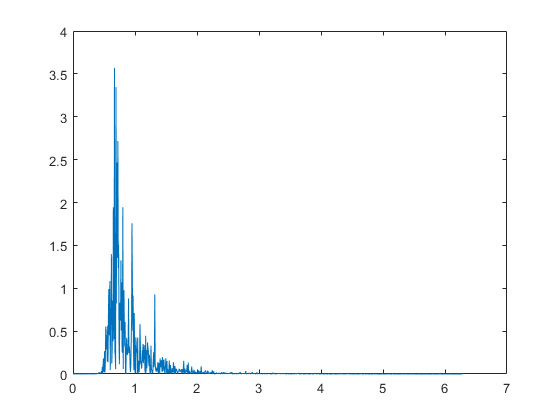

display(waveBartI)

We may now plot these using the standard plot function, and plotdB to get plots on the decibel scale

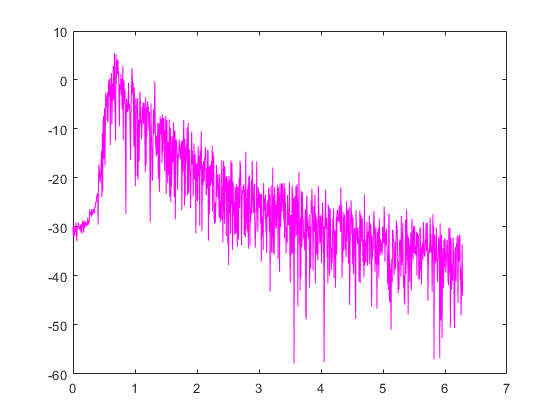

plot(waveI)

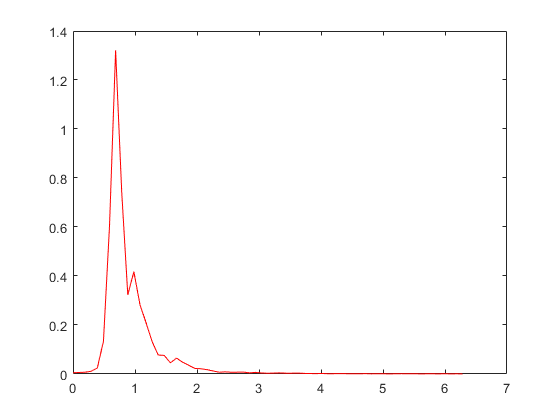

plotdB(waveI,'color','m')

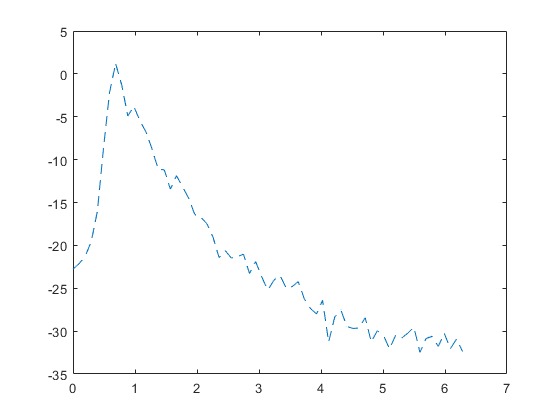

plot(waveBartI,'color','r')

plotdB(waveBartI,'linestyle','--')